# **TU: K-Nearest Neighbors**

Industrial AI & Automation by Y.K.Kim

Author: Jin Kwak/21900031

Mod: 2024.09.19

## Introduction

Classification with kNN

## Example: Classification Using Nearest Neighbors

**Distance Metrics**

Use [`pdist2`](https://kr.mathworks.com/help/stats/pdist2.html) to find the distance between a set of data and query points.

- Euclidean distance

- Standardized Euclidean distance

- Mahalanobis distance

- Cosine distance

***k*****-Nearest Neighbor Search and Radius Search**

- **Exhaustive Search(default)**

- **Kd-Tree (feature <10)**

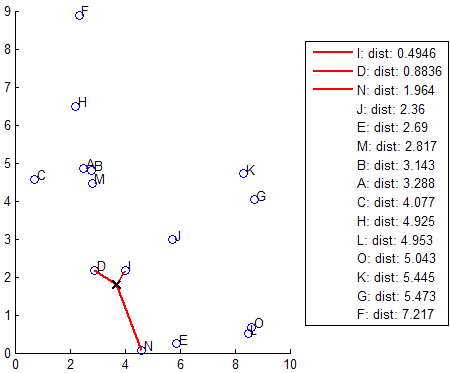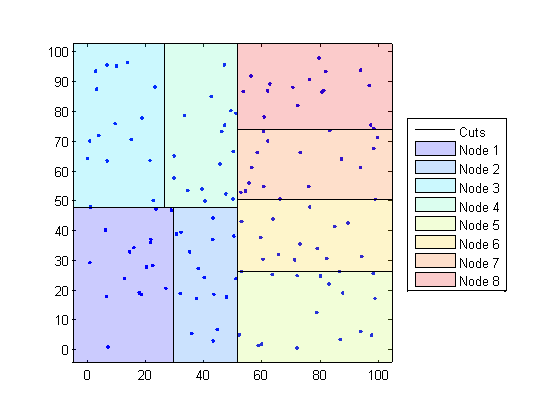

Randomly generate normally distributed data into two matrices. The number of rows can vary, but the number of columns must be equal. This example uses 2-D data for plotting.

rng(1) % For reproducibility

% Input Data
X = randn(50,2);

% Query
Y = randn(4,2);

h = zeros(3,1);
figure
h(1) = plot(X(:,1),X(:,2),'bx');
hold on
h(2) = plot(Y(:,1),Y(:,2),'rs','MarkerSize',10);
title('Heterogeneous Data')

**Mahalanobis distance**

Find the indices of the three nearest observations in `X` to each observation in `Y`.

k = 3;
[Idx,D] = knnsearch(X,Y,'Distance','mahalanobis','k',k);

`idx` and `D` are 4-by-3 matrices.

- `idx(j,1)` is the row index of the closest observation in `X` to observation *j* of `Y`, and `D(j,1)` is their distance.

- `idx(j,2)` is the row index of the next closest observation in `X` to observation *j* of `Y`, and `D(j,2)` is their distance.

- And so on.

Identify the nearest observations in the plot.

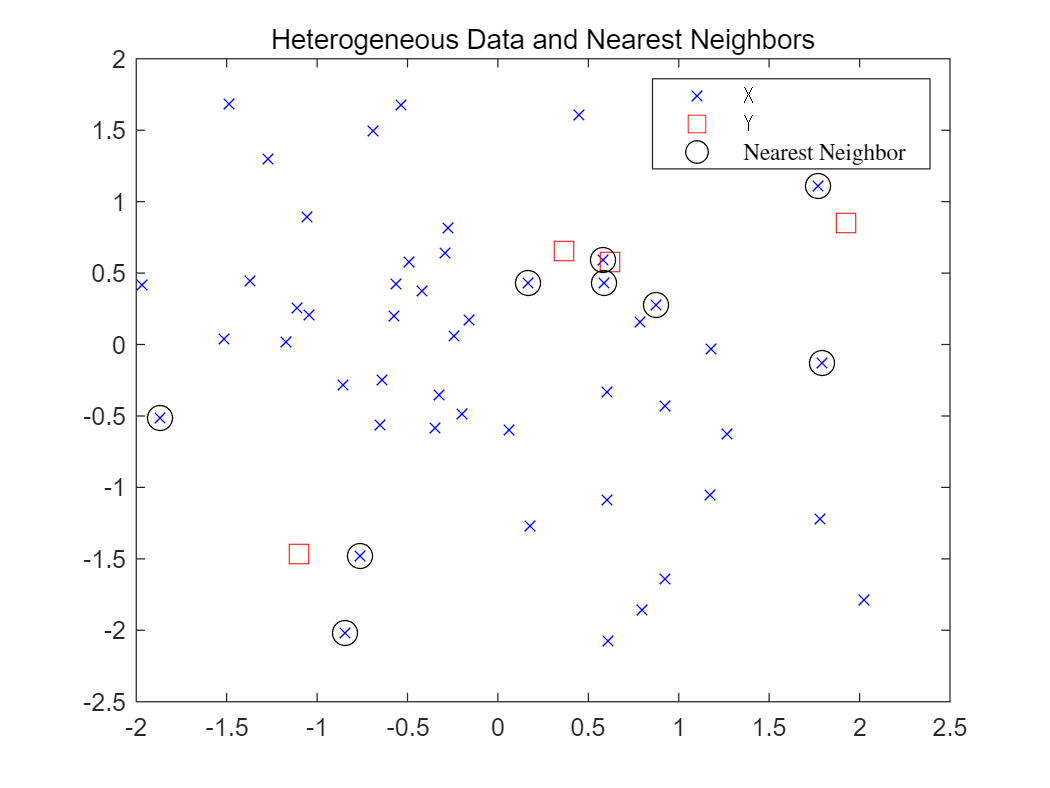

for j = 1:k
    h(3) = plot(X(Idx(:,j),1),X(Idx(:,j),2),'ko','MarkerSize',10);
end 
legend(h,{'\texttt{X}','\texttt{Y}','Nearest Neighbor'},'Interpreter','latex')
title('Heterogeneous Data and Nearest Neighbors')
hold off

# Exercise  

## Exercise : K-NN Classification with CWRU

### Dataset :  CWRU dataset features

- Given dataset contains many features extracted from CWRU dataset

- We will select 2~3 features for exercise

- Normal,  Outer and Inner Race Fault

clear

%% Train
load("../../Dataset/CWRU_selected_Dataset/Feature_data/sample_train.mat");

feature1 = "sv";                % skewness value of time data
feature2 = "ipf";               % impulse factor
X(:, 1) = table2array(glob_all_train(:, feature1));
X(:, 2) = table2array(glob_all_train(:, feature2));
Y = class_cwru_train;       % fault class
N = size(X,1);
tbl=table(X(:, 1),X(:, 2),Y);



%% Test
load("../../Dataset/CWRU_selected_dataset/Feature_data/sample_test.mat");

Xtest(:, 1) = table2array(glob_all_test(:, feature1));
Xtest(:, 2) = table2array(glob_all_test(:, feature2));
Ytest = class_cwru_test;                                 
Ntest=size(Xtest,1);
tblTest=table(Xtest(:, 1),Xtest(:, 2),Ytest);



#### Plot Test Data

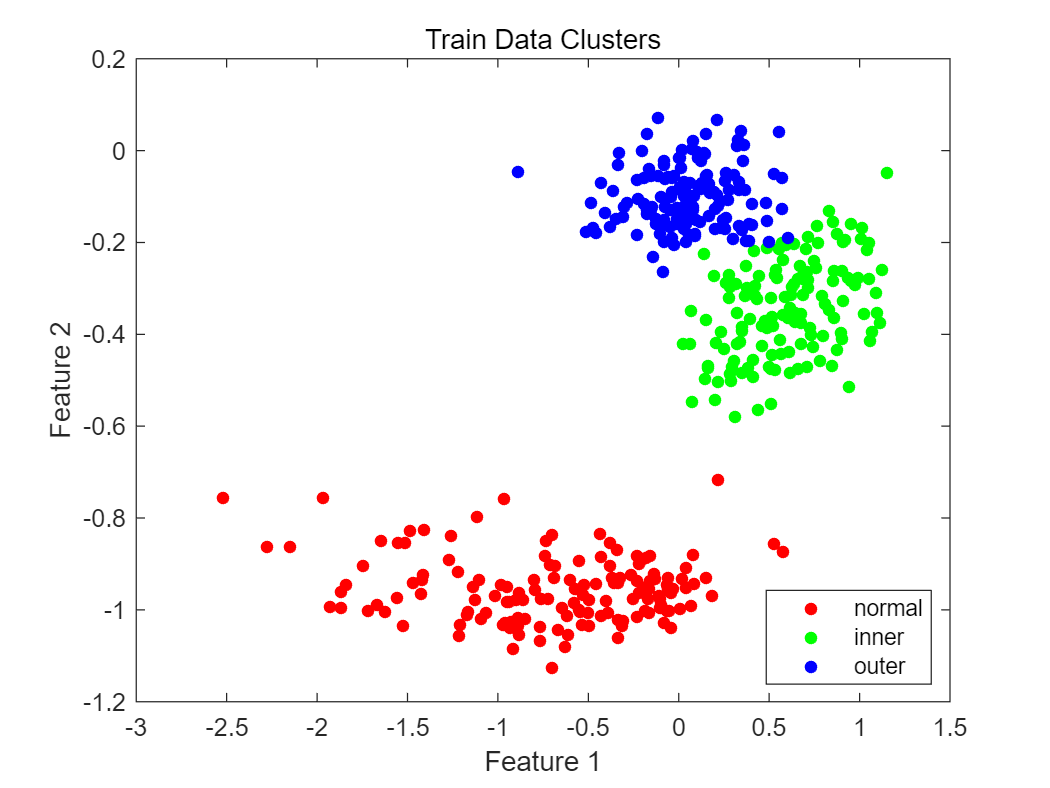

figure
gscatter(X(:,1),X(:,2),Y)
title('Train Data Clusters')
xlabel('Feature 1')
ylabel('Feature 2')

#### KNN Train

Construct the classifier using `fitcknn`.

rng(10); % For reproducibility

Mdl = fitcknn(X, Y)

Mdl =   ClassificationKNN
             ResponseName: 'Y'
    CategoricalPredictors: []
               ClassNames: {'inner'  'normal'  'outer'}
           ScoreTransform: 'none'
          NumObservations: 432
                 Distance: 'euclidean'
             NumNeighbors: 1


  Properties, Methods


#### Training loss (all train set)

Examine the resubstitution loss, which, by default, is the fraction of misclassifications from the predictions of `Mdl`. (For nondefault cost, weights, or priors, see [loss](docid:stats_ug.bs85nh7).).

loss_train = loss(Mdl, X, Y)

loss_train = 0

The classifier predicts incorrectly for 4% of the training data.

#### Cross-validation (k-fold)

Construct a cross-validated classifier from the model.

cv = cvpartition(Y,'KFold',10) 

cv = K-겹 교차 검증 분할
   NumObservations: 432
       NumTestSets: 10
         TrainSize: 389  388  388  389  389  389  389  389  389  389
          TestSize: 43  44  44  43  43  43  43  43  43  43

Examine the cross-validation loss, which is the average loss of each cross-validation model when predicting on data that is not used for training.

cv_val = crossval(Mdl,'CVPartition',cv);
error  = kfoldLoss(cv_val);

The cross-validated classification accuracy resembles the resubstitution accuracy. 

Therefore, you can expect `Mdl` to misclassify approximately 4% of new data, assuming that the new data has about the same distribution as the training data.

#### Predict test data

Predict the classification of test data

predictClass = predict(Mdl, Xtest)

predictClass = 108×1 cell 배열
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}


**Calculate the loss  of Test**

%%% YOUR CODE GOES HERE
loss_test=loss(Mdl, Xtest, Ytest)

loss_test = 0

**Plot  Confusion matrix of Test data**

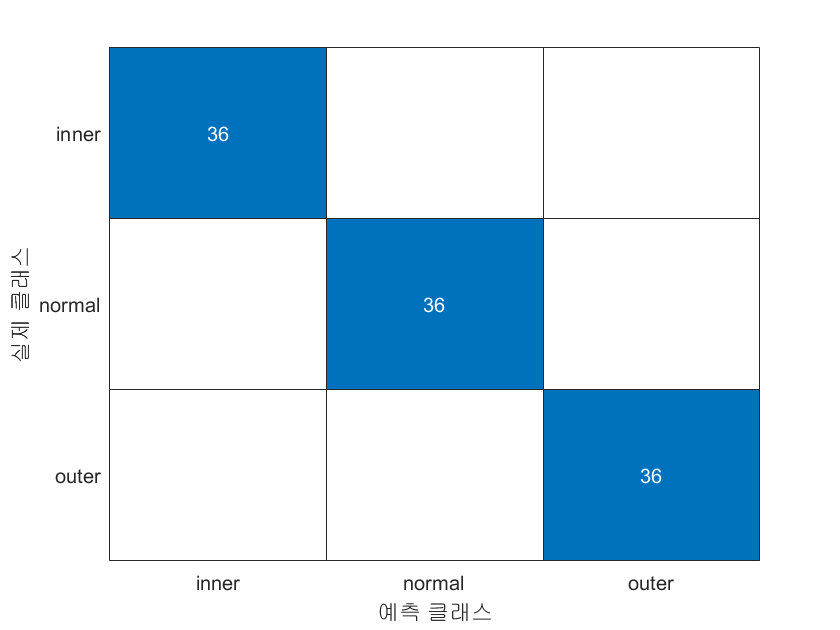

%%% YOUR CODE GOES HERE
conf_mat = confusionchart(Ytest, predictClass);

**Plot  Test Results and  Misclassified Test data**

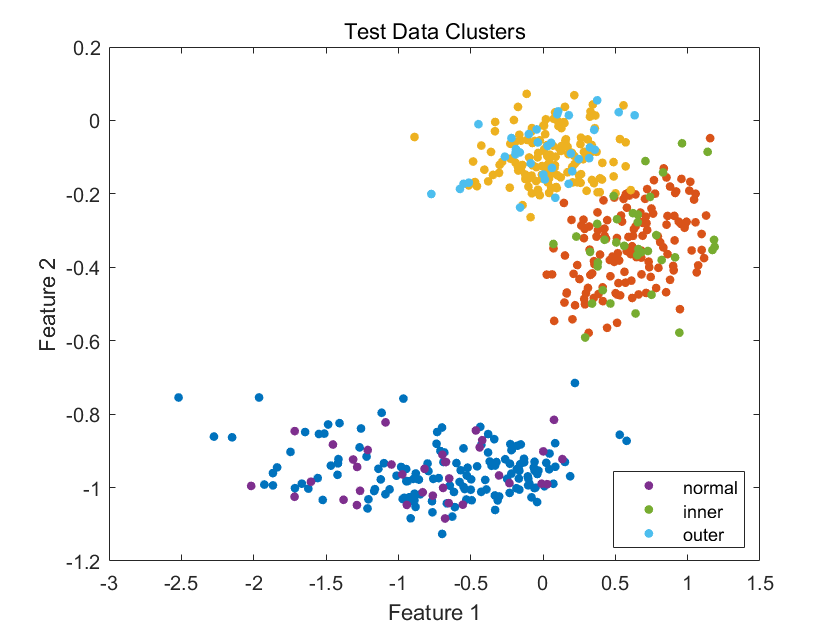

%%% YOUR CODE GOES HERE
bad = ~strcmp(predictClass,Ytest);
color = lines(6);               % Generate color values
figure
gscatter(X(:,1),X(:,2),Y, color(1:3,:))
hold on
gscatter(Xtest(:,1),Xtest(:,2),Ytest, color(4:6,:))
hold on;
plot(Xtest(bad,1), Xtest(bad,2), 'kx');
hold off;
title('Test Data Clusters')
xlabel('Feature 1')
ylabel('Feature 2')

#### Optimization of Fitted KNN

|=====================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   | NumNeighbors |     Distance |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |
|=====================================================================================================|
|    1 | Best   |    0.013889 |     0.14524 |    0.013889 |    0.013889 |            3 |    minkowski |


|    2 | Accept |    0.018519 |    0.064981 |    0.013889 |    0.014332 |           18 |    cityblock |


|    3 | Accept |    0.078704 |    0.039656 |    0.013889 |      0.0153 |          141 |    euclidean |
|    4 | Accept |     0.31713 |     0.08292 |    0.013889 |    0.021225 |            2 |       cosine |
|    5 | Accept |    0.018519 |    0.035891 |    0.013889 |    0.014504 |            2 |    minkowski |
|    6 | Accept |     0.05787 |    0.080052 |    0.013889 |    0.014402 |          215 |   seuclidean |
|    7 | Accept |     0.11574 |    0.033154 |    0.013889 |    0.013982 |          215 |    minkowski |
|    8 | Accept |    0.016204 |    0.036409 |    0.013889 |    0.014017 |            1 |    cityblock |
|    9 | Accept |    0.016204 |    0.029888 |    0.013889 |    0.014523 |            1 |   seuclidean |
|   10 | Accept |    0.016204 |    0.029157 |    0.013889 |     0.01456 |            3 |    chebychev |
|   11 | Accept |     0.16898 |    0.042738 |    0.013889 |    0.013956 |          215 |    chebychev |
|   12 | Accept |    0.016204 |    0.030166 |    0.013889 |    0

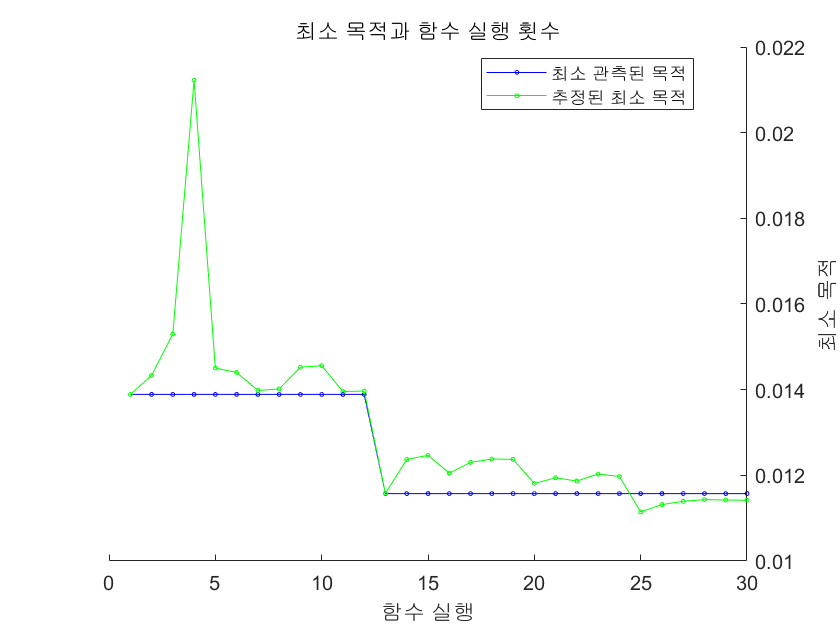

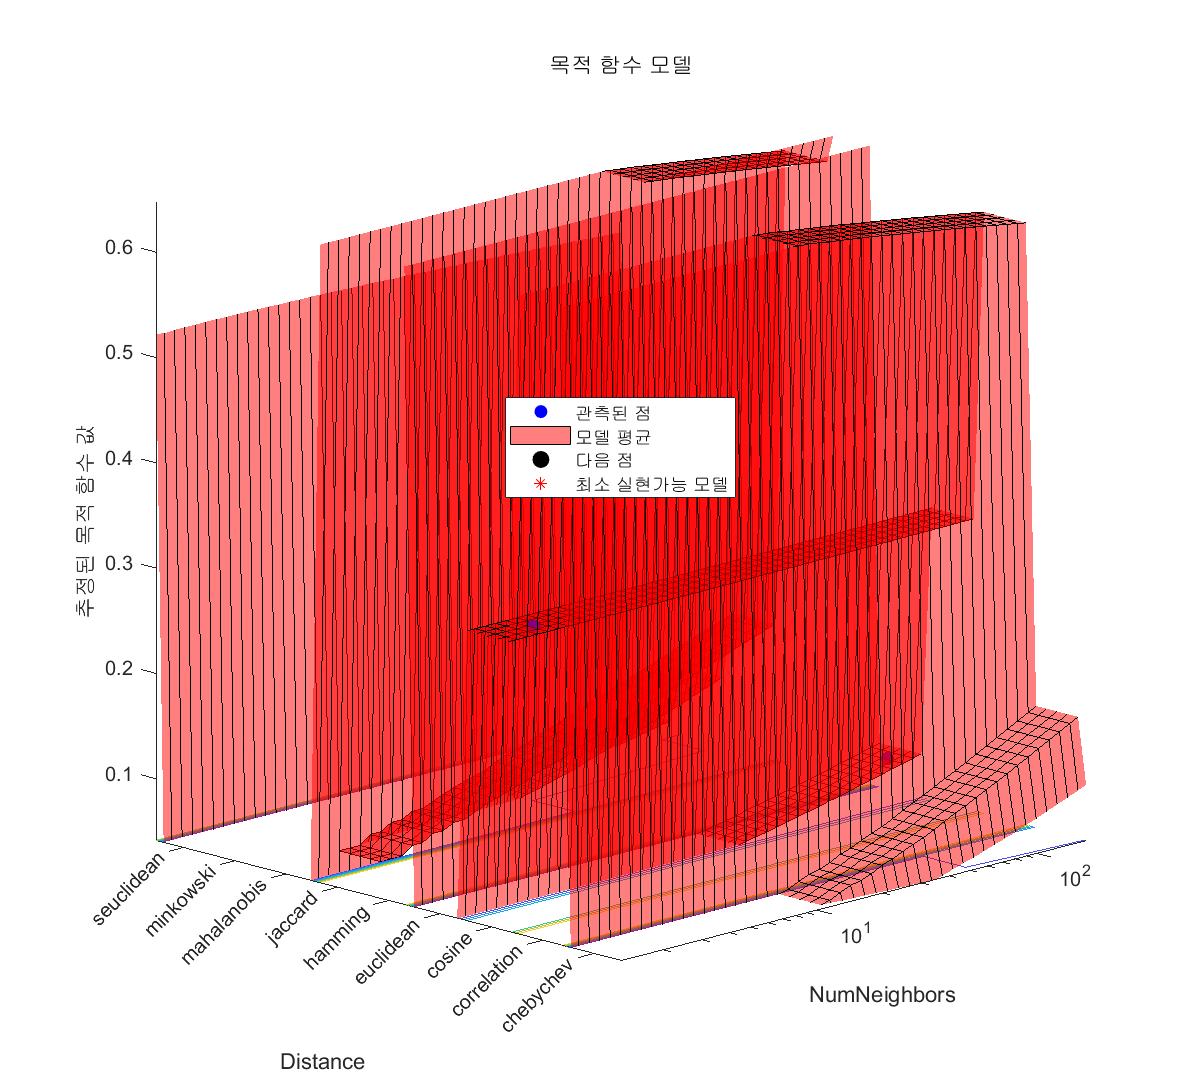


__________________________________________________________
최적화가 완료되었습니다.
MaxObjectiveEvaluations 30회에 도달했습니다.
총 함수 실행 횟수: 30
총 경과 시간: 14.838초
총 목적 함수 실행 시간: 1.2781

최선의 관측된 실현가능점:
    NumNeighbors     Distance 
    ____________    __________

         7          seuclidean

관측된 목적 함수 값 = 0.011574
추정된 목적 함수 값 = 0.012228
함수 실행 시간 = 0.030669

최선의 추정된 실현가능점(모델에 따라 다름):
    NumNeighbors     Distance 
    ____________    __________

         4          seuclidean

추정된 목적 함수 값 = 0.011418
추정된 함수 실행 시간 = 0.03375



Mdl =   ClassificationKNN
                         ResponseName: 'Y'
                CategoricalPredictors: []
                           ClassNames: {'inner'  'normal'  'outer'}
                       ScoreTransform: 'none'
                      NumObservations: 432
    HyperparameterOptimizationResults: [1×1 BayesianOptimization]
                             Distance: 'seuclidean'
                         NumNeighbors: 4


  Properties, Methods


Mdl = fitcknn(X,Y,'OptimizeHyperparameters','auto',...
    'HyperparameterOptimizationOptions',...
    struct('AcquisitionFunctionName','expected-improvement-plus'))

 Compare performance of KNN with other classification methods

KNN: good for low-dimension data (curse of dimensionality)

Training: Lazy Learning Algorithm

Easy to understand but slow for prediction

Depends on number of neighbors or distance